clc; clear;
if bdIsLoaded('Flightsim_aircraft')
    set_param('Flightsim_aircraft', 'SimulationCommand', 'stop');
end

ac = Aircraft();
ac.mass.set_mass_properties(9300, 55800, 63100, 118000, 0, 0, 0, [0 0 0]);
ac.mass.add_fuel_tank([0 0 0], 3000, 'distributed');
ac.mass.add_fuel_tank([-2 0 0], 1500, 'distributed');
ac.mass.set_fuel_mass(2400);
ac.geometry.wing_area              = 27.87;
ac.geometry.wing_span              = 9.14;
ac.geometry.mean_aerodynamic_chord = 3.45;
ac.aero.set_lookup(@F16Lookup);

cfg = ac.get_configurator();
cfg.add_control_surface('name','aileron','surface_type','aileron','classification','primary','axis',[1 0 0], ...
    'max_deflection',deg2rad(20),'min_deflection',deg2rad(-20),'dCl',0.05,'dCm',0,'dCn',0);
cfg.add_control_surface('name','elevator','surface_type','elevator','classification','primary','axis',[0 1 0], ...
    'max_deflection',deg2rad(25),'min_deflection',deg2rad(-25),'dCl',0,'dCm',0,'dCn',0);
cfg.add_control_surface('name','rudder','surface_type','rudder','classification','primary','axis',[0 0 1], ...
    'max_deflection',deg2rad(30),'min_deflection',deg2rad(-30),'dCl',0,'dCm',0,'dCn',-0.08);
cfg.add_propulsive_element('name','F100_PW_229','element_type','turbofan_afterburning','max_output',128992, ...
    'position',[-1.5 0 0],'direction',[1 0 0],'fuel_rate',2.5, ...
    'thrust_model',@(thr,M,alt,V,rho) F100ThrustModel(thr, M, alt, V, rho, 128992));

n_cs    = numel(ac.control_surfaces);
n_pe    = numel(ac.propulsive_elements);
n_total = n_cs + n_pe;


segments = struct('type',{},'altitude',{},'mach',{},'mach_end',{},'gamma',{},'gamma_end',{}, ...
                  'h_start',{},'h_end',{},'duration',{},'distance',{},'velocity',{},'V0',{},'V1',{});

segments(1).type      = 'climb_descent';
segments(1).h_start   = 7000;
segments(1).h_end     = 9144;
segments(1).mach      = 0.55;
segments(1).mach_end  = 0.60;
segments(1).gamma     = deg2rad(7);
segments(1).gamma_end = deg2rad(0);

segments(2).type      = 'hold_time';
segments(2).altitude  = 9144;
segments(2).mach      = 0.60;
segments(2).duration  = 600;
segments(2).gamma     = 0;
segments(2).gamma_end = 0;

segments(3).type      = 'climb_descent';
segments(3).h_start   = 9144;
segments(3).h_end     = 5000;
segments(3).mach      = 0.60;
segments(3).mach_end  = 0.50;
segments(3).gamma     = deg2rad(0);
segments(3).gamma_end = deg2rad(-5);

planner = ac.get_mission_planner(0.25);
planner.build_mission(segments);
planner.compute_trim_schedule('dh_m', 300, 'max_iters', 15000, 'tol', 1e-4);
planner.export_to_workspace('blend_fraction', 0.3);


[climb_descent] h=7000m M=0.550 → OK  α=5.69°  thr=0.544
[climb_descent] h=7200m M=0.555 → OK  α=5.79°  thr=0.529
[climb_descent] h=7500m M=0.562 → OK  α=5.95°  thr=0.504
[climb_descent] h=7800m M=0.569 → OK  α=6.11°  thr=0.477
[climb_descent] h=8100m M=0.576 → OK  α=6.28°  thr=0.448
[climb_descent] h=8400m M=0.583 → OK  α=6.45°  thr=0.416
[climb_descent] h=8700m M=0.590 → OK  α=6.64°  thr=0.380
[climb_descent] h=9000m M=0.597 → OK  α=6.84°  thr=0.315
[climb_descent] h=9144m M=0.600 → OK  α=6.92°  thr=0.321
[hold_time] h=9144m M=0.600 → OK  α=6.92°  thr=0.321
[climb_descent] h=9144m M=0.600 → OK  α=6.92°  thr=0.321
[climb_descent] h=9000m M=0.597 → OK  α=6.84°  thr=0.315
[climb_descent] h=8700m M=0.589 → OK  α=6.68°  thr=0.276
[climb_descent] h=8400m M=0.582 → OK  α=6.53°  thr=0.249
[climb_descent] h=8100m M=0.575 → OK  α=6.38°  thr=0.224
[climb_descent] h=7800m M=0.568 → OK  α=6.25°  thr=0.201
[climb_descent] h=7500m M=0.560 → OK  α=6.11°  thr=0.180
[climb_descent] h=7200m M=0.553 → O

Duration: 2749.5 s (45.8 min)
Points  : 11001
Alt [0] : 7000.0 m  |  z [0]: -7000.0 m


thr_idx = n_cs + 1;
fprintf('\nAltitude : %.0f m\n',  -initial_state(3));


Altitude : 7000 m


fprintf('Velocity : %.1f m/s\n', norm(initial_state(4:6)));

Velocity : 171.8 m/s


fprintf('Alpha    : %.2f deg\n', rad2deg(atan2(initial_state(6), initial_state(4))));

Alpha    : 5.69 deg


fprintf('Elevator : %.2f deg\n', rad2deg(initial_controls(2)));

Elevator : -0.56 deg


fprintf('Throttle : %.3f\n',     initial_controls(thr_idx));

Throttle : 0.544


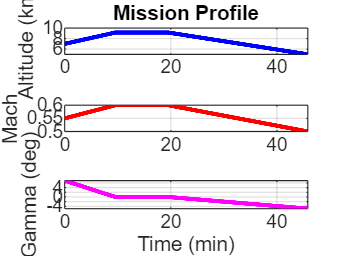


planner.plot_mission();

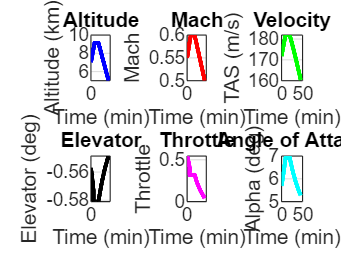


figure('Name','Trim Schedule');
alpha_rad = atan2(mission.state_profile(6,:), mission.state_profile(4,:));

subplot(2,3,1)
plot(mission.time_vector/60, mission.altitude_profile/1000,'b','LineWidth',2); grid on
xlabel('Time (min)'); ylabel('Altitude (km)'); title('Altitude')

subplot(2,3,2)
plot(mission.time_vector/60, mission.mach_profile,'r','LineWidth',2); grid on
xlabel('Time (min)'); ylabel('Mach'); title('Mach')

subplot(2,3,3)
plot(mission.time_vector/60, mission.velocity_profile,'g','LineWidth',2); grid on
xlabel('Time (min)'); ylabel('TAS (m/s)'); title('Velocity')

subplot(2,3,4)
plot(mission.time_vector/60, rad2deg(mission.control_profile(2,:)),'k','LineWidth',2); grid on
xlabel('Time (min)'); ylabel('Elevator (deg)'); title('Elevator')

subplot(2,3,5)
plot(mission.time_vector/60, mission.control_profile(thr_idx,:),'m','LineWidth',2); grid on
xlabel('Time (min)'); ylabel('Throttle'); title('Throttle')

subplot(2,3,6)
plot(mission.time_vector/60, rad2deg(alpha_rad),'c','LineWidth',2); grid on
xlabel('Time (min)'); ylabel('Alpha (deg)'); title('Angle of Attack')